# Homework 4

**Sebastian Aguilera Novoa**

## **1. Unconstrained minimization**

In this exercise we are going to implement different Newton methods to solve the following problem


$$\min_{x, y \in \mathbb{R}} \;\underbrace{\frac{1}{2}(x-1)^2+\frac{1}{2 }\left(10\left(y-x^2\right)\right)^2+\frac{1}{2} y^2}_{=: f(x, y)=z}$$


Plot the objective function $f(x,y)$ to get an idea of the shape is this.

%{
import casadi.*
x = SX.sym('x'); y = SX.sym('y');
qp = struct('x',[x;y], 'f',0.5*(x-1)^2+0.5*(10*(y-x^2))^2+0.5*y^2);
S = qpsol('S', 'qpoases', qp);
disp(S)
r = S('lbg',0);

x_opt = r.x;
disp(r.x)
%}

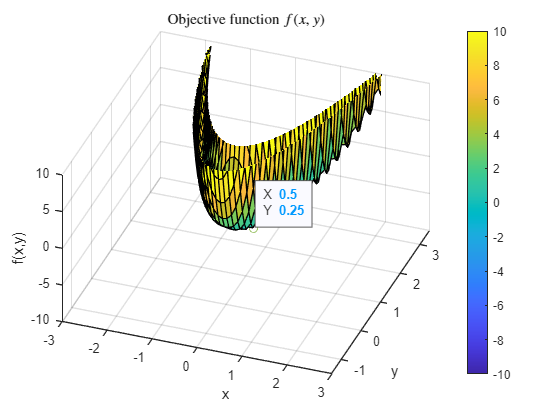

f = @(x,y) 0.5*(x-1).^2 +0.5*(10*(y-x.^2)).^2 + 0.5*y.^2;
%[X,Y] = meshgrid(-10:0.5:10,-20:0.5:30);
[X,Y] = meshgrid(-10:0.1:10,-10:0.1:10);
hold on
surf(X,Y, f(X,Y))
plot(0.5,0.25, 'o')
hold off
zlim([-10 0.1e2]); view([-41 70])
colorbar(); clim([-10 0.1e2])
xlim([-3 3]); ylim([-1.5 3.5])
xlabel('x'); ylabel('y'); zlabel('f(x,y)')
title('Objective function $f(x,y)$', Interpreter='latex')
ax = gca;
chart = ax.Children(1);
datatip(chart,0.5,0.25,0);
view([20.0 46.2])

f(0.5,0.5^2)

ans = 0.1563

### a) Gradian and Hessian

First get in papper, the gradient and Hessian matrix of $f(x,y)$. Then, rewrite it in the form $f(x,y) = \frac{1}{2} || R(x,y)||^2_2$ where $R:\mathbb{R}^2 \to \mathbb{R}^3$ is the residual function. Determine the Hessian by the Gauss-Newton method and compare it with the exact. When do the two matrices coincide?


$$\nabla f (x,y)= \Big(x-1+10(y-x^2)(-2x)10,\; 10(y-x^2)10+y \Big)\\
\quad \;  = \Big(x-1-200xy+200x^3, \; -100x^2+101y \Big)
$$


The Jacobian

$\nabla^2 f (x,y) = \pmatrix{
\frac{\partial^2 f}{\partial x^2} & \frac{\partial^2 f}{\partial x \partial y} \cr
\frac{\partial^2 f}{\partial y \partial x} & \frac{\partial^2 f}{\partial y^2} } = \pmatrix{
600x^2-200y+1 & -200 x \cr -200x & 101}$                    (1)

but this problem can be formulated as a least saquare problem


$$\min_{x, y \in \mathbb{R}} \; \frac{1}{2} || R(x,y)||^2_2$$


with


$$R(x,y ) =  \Big( x-1, 10(y-x^2), y\Big)\\
\frac{1}{2} || R(x,y)||^2_2 = \frac{1}{2}    \Big[ (x-1)^2+ (10(y-x^2))^2+y^2\Big]$$


that gives the same problem. Now let's calculate the Jacobian to the new vector field $R$ and then approximate the Hessian by this Jacobian


$$J = \nabla R = \pmatrix{
\frac{\partial R_1}{\partial x} & \frac{\partial R_1}{\partial y} \cr
\frac{\partial R_2}{\partial x} & \frac{\partial R_2}{\partial y} \cr
\frac{\partial R_3}{\partial x} & \frac{\partial R_3}{\partial y} } =
\pmatrix{
1 & 0 \cr
-20x & 10 \cr
0 & 1  
}$$


Hessian approximantion by Newton Gauss method


$$\approx J^T J = \pmatrix{
1 & 0 \cr
-20x & 10 \cr
0 & 1  
}^T \pmatrix{
1 & 0 \cr
-20x & 10 \cr
0 & 1  
} = 
\pmatrix{
1 & -20x & 0 \cr
0 & 10 & 1  
} \pmatrix{
1 & 0 \cr
-20x & 10 \cr
0 & 1  
} \\
= \pmatrix{1 +400x^2 & -200x \cr
-200x & 101}$$


then (1) conincide with the last matrix if and only if 


$$1+400x^2 = 600x^2-200y+1\\
200 y =200x^2\\
y = x^2 $$


then the optimization problem is


$$\min_{x \in \mathbb{R}} \; \frac{1}{2} || R(x,y)||^2_2\\
\quad \text{s.t.} \qquad y =  x^2$$


with


$$R(x) = R\left(x,  x^2 \right) =  \Big( x-1, 10\left( x^2-x^2\right),  x^2 \Big)\\
\frac{1}{2} || R(x)||^2_2 = \frac{1}{2}    \Big[ (x-1)^2+ x^2 \Big] = \frac{1}{2} (2x^2-2x+1)$$


which is equivalent to solve


$$\min_{x \in \mathbb{R}} \;  x^2-x+\frac{1}{2} = g(x)$$



$$x = \frac{1}{2}, g(x) = \frac{1}{4}$$


### b) Newton Method

Implement your own Newton method using the Hessian and complete steps. Start from the inital value $(x_0,y_0)=(1,1)$ and use it as a stop condition $|| \nabla f (x_k, y_k)||_\infty \leq 10^3$. Keep a track over the iterations $(x_k,y_k)$ and add it to the contour plot.

f        = @(x) 0.5*(x(1)-1)^2 +0.5*(10*(x(2)-x(1)^2))^2 + 0.5*x(2)^2;
Gradient = @(x) [200*x(1)^3+x(1)-200*x(1)*x(2)-1; -100*x(1)^2+101*x(2)]; % G(x) = H(x,y) 
Hessian  = @(x) [600*x(1)^2+1-200*x(2) -200*x(1); -200*x(1) 101];        % H(x) = H(x,y) 

R        = @(x) [x(1)-1; 10*(x(2)-x(1)^2); x(2)];
Jacobian = @(x) [1 0; -20*x(1) 10; 0 1];


$$f(x_k+t) \approx f(x_k) + \nabla f (x_k) t + \frac{1}{2} \nabla^2 f (x_k) t^2$$


has a minimum 


$$\frac{d}{dt} f(x_k+t) = \frac{d}{dt} \left(f(x_k) + \nabla f (x_k) t + \frac{1}{2} \nabla^2 f (x_k) t^2\right) = 0 \\
\nabla f (x_k) +  t = 0\\
t = - \nabla^2 f(x_k) ^{-1} \nabla f (x_k) =  - \nabla^2 f_k ^{-1} \nabla f_k$$



$$x_{k+1} = x_k  -  \nabla^2f_k^{-1} \nabla f_k$$


x0 = [1; 1];

Newton = @(xk) -Jacobian(xk)\R(xk);
xk_Newton = Iteration(x0, Newton, Jacobian)

xk_Newton =     1.0000    0.6008    0.5884    0.5919    0.5908    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911
    1.0000    0.1996    0.3426    0.3468    0.3456    0.3460    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3

### c) Gauss- Newton Method

Update by adding a Newton type method that uses the Hessian of the Gauss-Newton method instead. Add the resultant iterations$(x_k,y_k)$  to the plot.

GaussNewton = @(xk) -(Jacobian(xk)'*Jacobian(xk))\(Jacobian(xk)'*R(xk));
xk_GN = Iteration(x0, GaussNewton , Jacobian)

xk_GN =     1.0000    0.6008    0.5884    0.5919    0.5908    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911    0.5911
    1.0000    0.1996    0.3426    0.3468    0.3456    0.3460    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459    0.3459 

### d) Add Regularization

Check how the steepest descent method works in this example. Now the Hessian approximation is $\alpha I$, where $\alpha$ is a positive scalar and $I$ is the identity matrix of appropiate size. What values does the algorithm converge for?

alpha = 0.01;
%JacobianReg = @(xk) Jacobian(xk)+alpha*eye()
%GaussNewton = @(xk) -(Jacobian(xk)'*Jacobian(xk))\(Jacobian(xk)'*R(xk));
%xk_GN = Iteration(x0, GaussNewton , Jacobian)

### e) Methods Performance

Compare the performance of the implemented methods. Consider the iteration path $(x_k,y_k)$, the number of iterations and the execution time. To measure the time, you can use the command `tic toc `from Matlab.

## 2. Methods Implementation

Armijo Rule: $$f\left(x_k+\alpha p_k\right) \leq f\left(x_k\right)+c_1 \alpha \nabla f_k^T p_k$,$

Iteration formula: $x_{k+1} = x_k+ \alpha_k p_k$

### 0) Comparison

Using each of the previous methods solve


$$\underset{x_1,x_2\in \mathbb{R}}{min} \quad \underbrace{100 (x_2-x_1)^2 +(1-x_1)^2}_{=f(x_1,x_2)}$$



$$f(x_1, x_2) = || R(x_1, x_2)||\\
R(x_1, x_2) = \big(10(x_2-x_1), 1-x_1\big)$$


Take as initial value $(1.5, 1.5)^T$, the optimum value is $(1,1)$. The algorithm output have to show a table with the following information


$$k \qquad x_k \qquad  f(x_k) \qquad \nabla f(x_k)  \qquad  p_k  \qquad  t^*$$


Compare the performance of the methods.

%{
f = @(x,y) 100*(y-x).^2 + (1-x).^2;
[X,Y] = meshgrid(-2:0.01:2,-2:0.01:2);

hold on
plot(1,1,'o')
surf(X,Y, f(X,Y))
hold off
ax = gca;
chart = ax.Children(1);
datatip(chart,1,1,0);

zlim([-1 0.1e2]);
colorbar(); clim([-1 0.1e2])
xlim([-2 2]); ylim([-2 2])
xlabel('x'); ylabel('y'); zlabel('f(x,y)')
title('Objective function $f(x,y)$', Interpreter='latex')
view([-45 45])
%}

Gradient and Hessian 


$$\nabla f= \big(-(2)100(x_2-x_1) -2 (1-x_1), (2)100(x_2-x_1)\big)\\
\nabla f= \big(200(x_1-x_2) -2 +2x_1, \;200(x_2-x_1)\big)\\
\nabla^2 f (x,y) = \pmatrix{
200+2 & -200 \cr -200  & 200} = \pmatrix{
202 & -200 \cr -200  & 200} $$


global c1 c2 alpha0 rho
global Armijo Wolfe StrongWolfe % Goldstein

f        = @(x) 100*(x(2)-x(1))^2 + (1-x(1))^2;
Gradient = @(x) [200*(x(1)-x(2))-2+2*x(1); 200*(x(2)-x(1))]; % G(x) = H(x,y) 
Hessian  = @(x) [202 -200; -200 200];        % H(x) = H(x,y) 

Armijo      = @(xk, f, Gradient, pk, alphak) f(xk+alphak*pk) <= f(xk)+c1*alphak*Gradient(xk)'*pk;
Wolfe       = @(xk, f, Gradient, pk, alphak) Gradient(xk+alphak*pk)'*pk >= c2 * Gradient(xk)'* pk;
StrongWolfe = @(xk, f, Gradient, pk, alphak) norm(Gradient(xk+alphak*pk)'*pk,2) >= c2 * norm(Gradient(xk)'* pk,2);
%Goldstein   = @(xk, f, Gradient, pk, alphak) f(xk)+(1-c)*alphak*Gradient(xk)'*pk <= f(xk)+c*alphak*Gradient(xk)'*pk;   

c1 = 1e-4; c2 = 0.9; alpha0 = 1; rho=1/2; %c1 = 1e-4

### a) Steepest Descent

Such that employs the backward globalization technique with Armijo rule.


$$p_k = \nabla f_k$$


x0 = [1.5 1.5]';

pk_func_SD = @(xk) -Gradient(xk);
[ks_SD, xks_SD, fks_SD, grad_SD, pks_SD, tstar_SD, I_SD] = MethodImpl(pk_func_SD, x0, Gradient, f, Armijo)

ks_SD =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


xks_SD =     1.5000    1.4922    1.4933    1.4892    1.4859    1.4742    1.4760    1.4747    1.4703    1.4699    1.4488    1.4526    1.4528    1.4412    1.4433    1.4429    1.4232    1.4266    1.4268    1.4160    1.4179    1.4175    1.3991    1.4022    1.4023    1.3922    1.3940    1.3935    1.3763    1.3791    1.3792    1.3698    1.3714    1.3705    1.3669    1.3667    1.3498    1.3530    1.3534    1.3440    1.3459    1.3456    1.3298    1.3328    1.3331    1.3243    1.3261    1.3258    1.3110    1.3137
    1.5000    1.5000    1.4969    1.4856    1.4870    1.4835    1.4799    1.4738    1.4745    1.4712    1.4629    1.4574    1.4536    1.4511    1.4472    1.4442    1.4362    1.4311    1.4276    1.4251    1.4215    1.4187    1.4110    1.4064    1.4031    1.4006    1.3973    1.3947    1.3873    1.3830    1.3800    1.3776    1.3745    1.3696    1.3703    1.3676    1.3616    1.3570    1.3539    1.3523    1.3490    1.3466    1.3408    1.3365    1.3336    1.3320    1.3290    1.3267    1.3211

fks_SD =     0.2500    0.2484    0.2447    0.2407    0.2362    0.2336    0.2281    0.2254    0.2229    0.2210    0.2215    0.2072    0.2051    0.2045    0.1981    0.1963    0.1961    0.1840    0.1822    0.1814    0.1760    0.1744    0.1736    0.1635    0.1619    0.1609    0.1563    0.1550    0.1538    0.1453    0.1439    0.1428    0.1389    0.1373    0.1358    0.1346    0.1364    0.1262    0.1249    0.1252    0.1206    0.1196    0.1207    0.1121    0.1110    0.1110    0.1072    0.1062    0.1068    0.0996


grad_SD =     1.0000   -0.5781    0.2603    1.7084    0.7493   -0.9201    0.1728    1.1176    0.1042    0.6754   -1.9355   -0.0652    0.7443   -1.1009    0.1082    0.6310   -1.7598   -0.0475    0.6937   -0.9959    0.1110    0.5897   -1.5997   -0.0319    0.6466   -0.9005    0.1129    0.5511   -1.4537   -0.0183    0.6029   -0.8138    0.1141    0.9164    0.0563    0.5412   -1.6742   -0.0864    0.6009   -0.9650    0.0614    0.5054   -1.5232   -0.0696    0.5597   -0.8741    0.0656    0.4720   -1.3856   -0.0547
         0    1.5625    0.7263   -0.7299    0.2226    1.8686    0.7792   -0.1683    0.8363    0.2644    2.8331    0.9703    0.1613    1.9832    0.7785    0.2548    2.6062    0.9007    0.1599    1.8278    0.7248    0.2453    2.3978    0.8363    0.1580    1.6849    0.6750    0.2359    2.2063    0.7766    0.1556    1.5534    0.6287   -0.1754    0.6776    0.1922    2.3737    0.7925    0.1058    1.6529    0.6303    0.1859    2.1829    0.7352    0.1065    1.5228    0.5865    0.1795    2.007

pks_SD =    -1.0000    0.5781   -0.2603   -1.7084   -0.7493    0.9201   -0.1728   -1.1176   -0.1042   -0.6754    1.9355    0.0652   -0.7443    1.1009   -0.1082   -0.6310    1.7598    0.0475   -0.6937    0.9959   -0.1110   -0.5897    1.5997    0.0319   -0.6466    0.9005   -0.1129   -0.5511    1.4537    0.0183   -0.6029    0.8138   -0.1141   -0.9164   -0.0563   -0.5412    1.6742    0.0864   -0.6009    0.9650   -0.0614   -0.5054    1.5232    0.0696   -0.5597    0.8741   -0.0656   -0.4720    1.3856    0.0547
         0   -1.5625   -0.7263    0.7299   -0.2226   -1.8686   -0.7792    0.1683   -0.8363   -0.2644   -2.8331   -0.9703   -0.1613   -1.9832   -0.7785   -0.2548   -2.6062   -0.9007   -0.1599   -1.8278   -0.7248   -0.2453   -2.3978   -0.8363   -0.1580   -1.6849   -0.6750   -0.2359   -2.2063   -0.7766   -0.1556   -1.5534   -0.6287    0.1754   -0.6776   -0.1922   -2.3737   -0.7925   -0.1058   -1.6529   -0.6303   -0.1859   -2.1829   -0.7352   -0.1065   -1.5228   -0.5865   -0.1795   -2.0077

tstar_SD = 0.0399

I_SD = 1324

### b) Newton 

Such that employs the backward globalization technique with Armijo rule.


$$p_k^N = -(\nabla^2 f_k)^{-1}\nabla f_k$$


pk_func_Newton = @(xk) -Hessian(xk)\Gradient(xk);
[ks_N, xks_N, fks_N, grad_N, pks_N, tstar_N, I_N] = MethodImpl(pk_func_Newton, x0, Gradient, f, Armijo)

ks_N =      1     2     3


xks_N =     1.5000    1.0000    1.0000
    1.5000    1.0000    1.0000


fks_N =     0.2500    0.0000         0


grad_N =     1.0000    0.0000         0
         0         0         0


pks_N =    -0.5000   -0.0000         0
   -0.5000   -0.0000         0


tstar_N = 0.0025

I_N = 3

### c) Quasi-Newton BFGS

Such that employs the backward globalization technique with Armijo rule


$$s_k = x_{k+1}-x_k, \qquad y_k = \nabla f_{k+1} - \nabla f_k, \qquad B_{k+1} s_k = y_k$$



$$B_{k+1} = B_k - \frac{B_k s_k s_k^T B_k}{s_k^T B_k s_k} + \frac{y_k y_k^T}{y_k^T y_k}$$



$$p_k = -B_k^{-1}\nabla f_k$$


[ks_BFGS, xks_BFGS, fks_BFGS, grad_BFGS, pks_BFGS, tstar_BFGS, I_BFGS] = MethodBFGS(x0, Gradient, f, Armijo)

ks_BFGS =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


xks_BFGS =     1.5000    1.4922    1.4889    1.4303    1.3889    0.6328    0.6365    0.6378    0.6422    0.6630    0.6699    0.6768    0.7222    0.9358    1.0387    1.0392    1.0395    1.0392    1.0287    0.9941    0.9646    0.9534    0.9442    0.9441    0.9629    1.0275    1.0430    1.0498    1.0520    1.0457    0.9782    0.9731    0.9716    0.9718    0.9733    0.9788    1.0047    1.0130    1.0125    1.0113    1.0089    1.0027    0.9906    0.9778    0.9774    0.9835    0.9945    1.0072    1.0129    1.0159
    1.5000    1.5000    1.4878    1.4483    1.3814    0.6198    0.6354    0.6395    0.6490    0.6828    0.6766    0.6759    0.7050    0.9455    1.0394    1.0398    1.0400    1.0391    1.0262    0.9887    0.9597    0.9496    0.9423    0.9433    0.9659    1.0335    1.0469    1.0521    1.0528    1.0439    0.9730    0.9709    0.9711    0.9718    0.9742    0.9810    1.0098    1.0147    1.0131    1.0112    1.0082    1.0009    0.9879    0.9760    0.9765    0.9838    0.9957    1.0086    1.01

fks_BFGS =     0.2500    0.2484    0.2391    0.2175    0.1570    0.1517    0.1322    0.1314    0.1327    0.1526    0.1135    0.1046    0.1069    0.0137    0.0015    0.0016    0.0016    0.0015    0.0015    0.0029    0.0036    0.0036    0.0035    0.0032    0.0023    0.0044    0.0034    0.0030    0.0028    0.0024    0.0031    0.0012    0.0008    0.0008    0.0008    0.0010    0.0025    0.0005    0.0002    0.0001    0.0001    0.0003    0.0008    0.0008    0.0006    0.0003    0.0002    0.0003    0.0004    0.0004


grad_BFGS =     1.0000   -0.5781    1.1975   -2.7360    2.2936    1.8642   -0.5121   -1.0508   -2.0835   -4.6247   -2.0062   -0.4681    2.8929   -2.0867   -0.0552   -0.0393   -0.0228    0.1054    0.5579    1.0542    0.9082    0.6747    0.2704    0.0633   -0.6699   -1.1462   -0.6975   -0.3693   -0.0559    0.4441    0.9814    0.3831    0.0309   -0.0569   -0.2227   -0.4913   -0.9955   -0.3120   -0.0835    0.0425    0.1635    0.3556    0.5248    0.3195    0.1300   -0.0929   -0.2514   -0.2823   -0.2490   -0.2104
         0    1.5625   -0.2197    3.5966   -1.5157   -2.5985   -0.2149    0.3264    1.3678    3.9507    1.3459   -0.1784   -3.4484    1.9582    0.1326    0.1178    0.1018   -0.0270   -0.5005   -1.0661   -0.9790   -0.7678   -0.3820   -0.1750    0.5957    1.2011    0.7835    0.4689    0.1598   -0.3528   -1.0251   -0.4370   -0.0878    0.0004    0.1694    0.4489    1.0050    0.3381    0.1086   -0.0200   -0.1457   -0.3502   -0.5437   -0.3639   -0.1753    0.0598    0.2403    0.2966    0.2

pks_BFGS = 1.0e-04 *

    0.0889
    0.1616


tstar_BFGS = 0.0173

I_BFGS = 286

### d) Newton 

Such that employs the backward globalization technique with the Dogleg trust region. 

function alphak = Backtracking(xk, f, Gradient, pk, Rule)
    global alpha0 rho
    alpha= alpha0;  %c = 0;
    while not(Rule(xk, f, Gradient, pk, alpha)) %&& c<100
        alpha = rho*alpha;
        %c = c+1;
    end
    %display(c)
    alphak = alpha;
end

function [Ks, Xks, Fks, Grad, Pks, tstar, I] = MethodBFGS(x0, Gradient, f, Armijo)
    tstart = tic;
    IterMax   = 2000; tol = 1e-8;
    Bk        = eye(2);
    ks        = [1];
    Gradients = [Gradient(x0)];
    pks       = [- Bk\Gradient(x0)];
    xks       = [x0];
    fks       = [f(x0)];
    
    
    for i=2:IterMax
        alphak = Backtracking(xks(:,end)', f, Gradient, pks(:,end), Armijo);
        
        
        xks    = [xks xks(:,end)+alphak*pks(:,end)];
        
        Gradients = [Gradients Gradient(xks(:,end))];
        pks       = [pks - Bk\Gradient(xks(:,end))];
        fks       = [fks f(xks(:,end))];
        ks        = [ks i];
        
        sk = xks(:,end) - xks(:,end-1);
        yk = Gradient(xks(:,end)) - Gradient(xks(:,end-1));
        Bk = Bk - (Bk*(sk*sk')*Bk')/(sk'*Bk*sk)+(yk*yk')/(yk'*yk);

        if norm(xks(:,end)-xks(:,end-1),2) < tol 
            break
        end
    end
    Ks = ks;   Xks = xks; Pks = pks;
    Fks = fks; Grad = Gradients;
    tstar = toc(tstart); I = i;
    %display(tstar);
end


function [Ks, Xks, Fks, Grad, Pks, tstar, I] = MethodImpl(pk_func, x0, Gradient, f, Armijo)
    tstart = tic;
    IterMax   = 2000; tol = 1e-8;
    ks        = [1];
    Gradients = [Gradient(x0)];
    pks       = [pk_func(x0)];
    xks       = [x0];
    fks       = [f(x0)];
    
    for i=2:IterMax
        alphak = Backtracking(xks(:,end)', f, Gradient, pks(:,end), Armijo);
        xks    = [xks xks(:,end)+alphak*pks(:,end)];
        
        Gradients = [Gradients Gradient(xks(:,end))];
        pks       = [pks pk_func(xks(:,end))];
        fks       = [fks f(xks(:,end))];
        ks        = [ks i];
        
        if norm(xks(:,end)-xks(:,end-1),2) < tol 
            break
        end
    end
    Ks = ks;   Xks = xks; Pks = pks;
    Fks = fks; Grad = Gradients;
    tstar = toc(tstart); I = i;
    %display(tstar);
end

function [xk,count] = Iteration(x0, func, Jacobian)
    xk = [x0];
    c = 0; MaxIter = 500; tol = 10^3;
    
    while (norm(Jacobian(xk(:,end)), "inf")  <= tol) && (c < MaxIter)
        xk = [xk xk(:,end)+func(xk(:,end))];
    
        c=c+1;
        %display(norm(Jacobian(xk),"inf"))
        %display(c)
    end
    count = c;
end